load points2D_Set2.mat x y

rng(0);

% First get the size of data
ARR_SIZE = size(x);
ARR_SIZE = ARR_SIZE(1);

% First get Average
x_ave = sum(x)/ARR_SIZE;
y_ave = sum(y)/ARR_SIZE;

% Array to manually calculate covariance
My_cov = zeros(2,2);
for i=1:ARR_SIZE
    My_cov(1,1) = My_cov(1,1) + (x(i)-x_ave)^2;
    My_cov(2,2) = My_cov(2,2) + (y(i)-y_ave)^2;
    My_cov(1,2) = My_cov(1,2) + (x(i)-x_ave)*(y(i)-y_ave);
    My_cov(2,1) = My_cov(2,1) + (x(i)-x_ave)*(y(i)-y_ave);
end

% Calculating sample covariance
My_cov = My_cov/(ARR_SIZE-1);

% Getting the eigen values
[V, D] = eig(My_cov);

% The eigen vector with maximum eigen value
% Note that eig function returns eigen vectors with increasing eigen values
vec = V(:,2);

% The slope of the best fit line will be slop of this eigen vector 
m = vec(2)/vec(1);

% The c in y=mx+c for the equation of line can be found by plugging in the
% means of x and y
c = y_ave - m*x_ave;

% Now we plot the line and the data
plot_x = -2:0.01:2;
plot_y = m*plot_x + c;
plot(plot_x,plot_y);
hold;

Current plot held


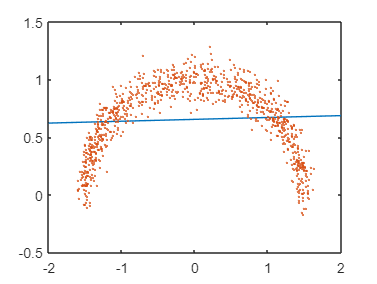

scatter(x,y,1);